## 2 a)

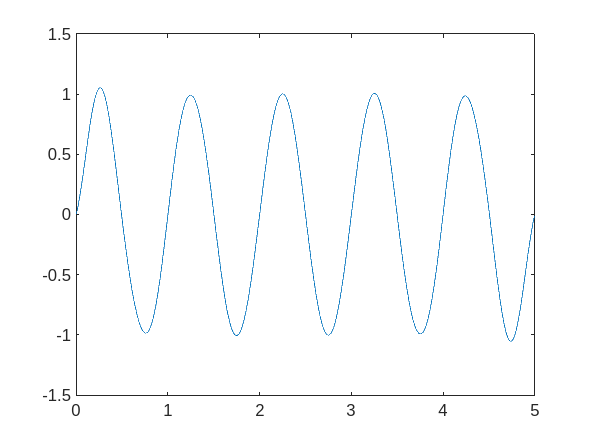

Ta = .2;
t = 0 : Ta: 5-1/100;
x = sin(2*pi*t);
[y,t] = ReconstroiSinal(x, Ta);
plot(t,y);

## b)

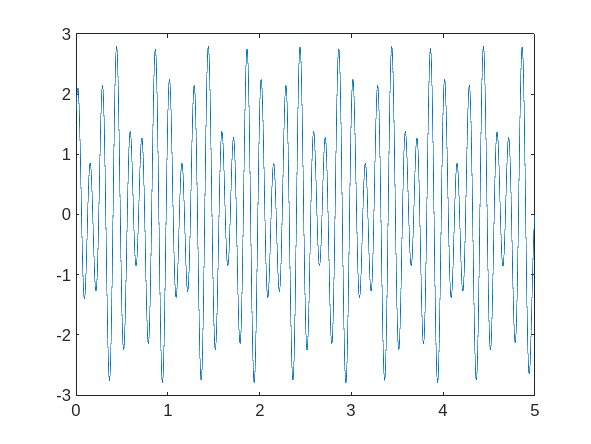

Ta = 0.04;
t = 0: Ta : 5-1/100;
x = sin(10*pi*t)+cos(14*pi*t)+cos(14*pi*t-pi/4);
[y, t] = ReconstroiSinal(x,Ta);
plot(t,y);

## II (1. 2. 3. -> 2 bits)

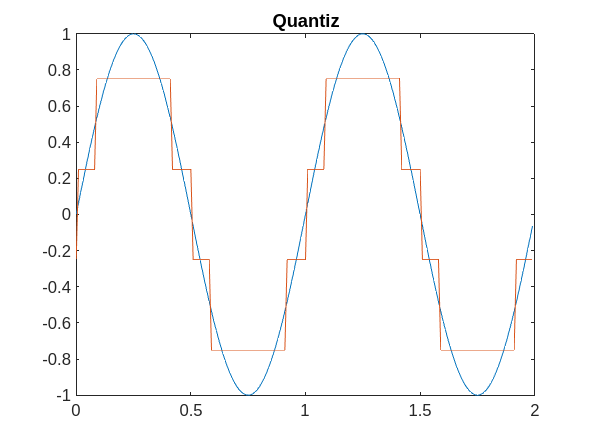

Ta = 0.01;
t = (0 : Ta : 2-Ta)';
sig = sin(2*pi*t);
nbit = 2;
amp=2*max(abs(sig));
Npal = 2^nbit;
Delta = amp/Npal;
partition = [-1+2*Delta/2 : Delta : 1-Delta/2];
codebook = [-1+Delta/2 : Delta : 1-Delta/2];
[index,quants] = quantiz(sig,partition,codebook);

figure(1);
plot(t,sig,t,quants);
title("Quantiz")

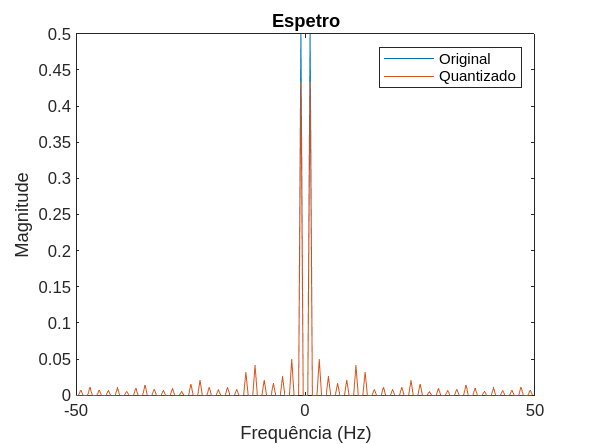


[X,f] = Espetro(sig,Ta);
legend("Original");
hold on;
[X,f] = Espetro(quants,Ta);
legend("Quantizado");
hold off;
legend("Original", "Quantizado");

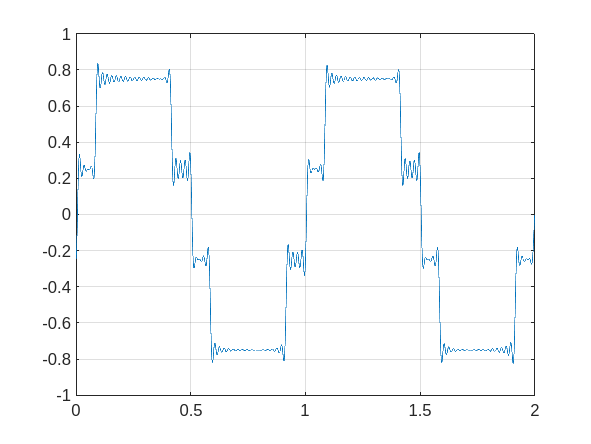


[y, t] = ReconstroiSinal(quants, Ta);
plot(t, y)
grid

## 3 bits

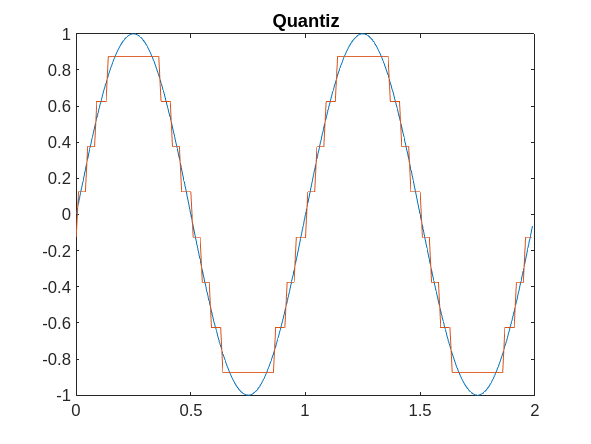

Ta = 0.01;
t = (0 : Ta : 2-Ta)';
sig = sin(2*pi*t);
nbit = 3;
amp=2*max(abs(sig));
Npal = 2^nbit;
Delta = amp/Npal;
partition = [-1+2*Delta/2 : Delta : 1-Delta/2];
codebook = [-1+Delta/2 : Delta : 1-Delta/2];
[index,quants] = quantiz(sig,partition,codebook);

figure(2);
plot(t,sig,t,quants);
title("Quantiz")

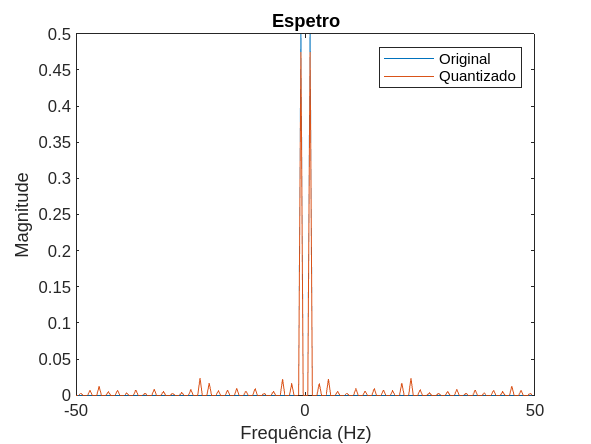


[X,f] = Espetro(sig,Ta);
legend("Original");
hold on;
[X,f] = Espetro(quants,Ta);
legend("Quantizado");
hold off;
legend("Original", "Quantizado");

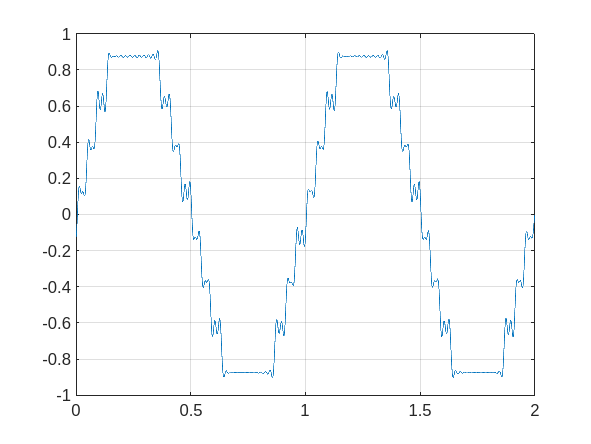


[y, t]= ReconstroiSinal(quants, Ta);
plot(t, y)
grid

## 4 bits

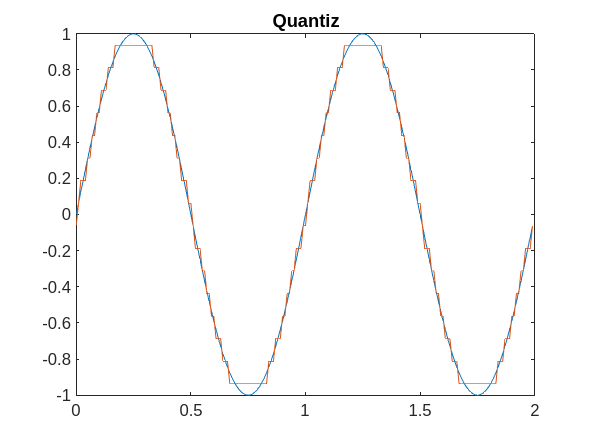


Ta = 0.01;
t = (0 : Ta : 2-Ta)';
sig = sin(2*pi*t);
nbit = 4;
amp=2*max(abs(sig));
Npal = 2^nbit;
Delta = amp/Npal;
partition = [-1+2*Delta/2 : Delta : 1-Delta/2];
codebook = [-1+Delta/2 : Delta : 1-Delta/2];
[index,quants] = quantiz(sig,partition,codebook);

figure(3);
plot(t,sig,t,quants);
title("Quantiz")

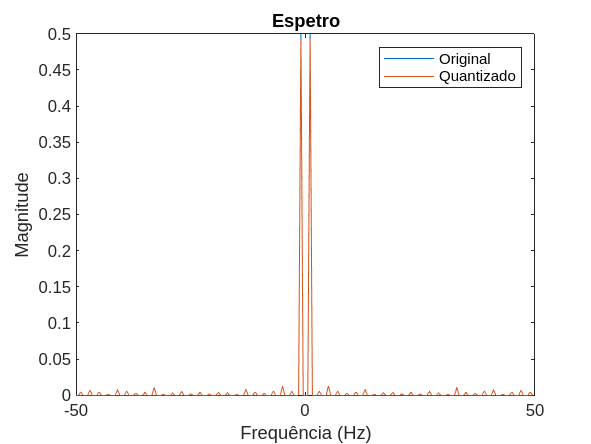


[X,f] = Espetro(sig,Ta);
legend("Original");
hold on;
[X,f] = Espetro(quants,Ta);
legend("Quantizado");
hold off;
legend("Original", "Quantizado");

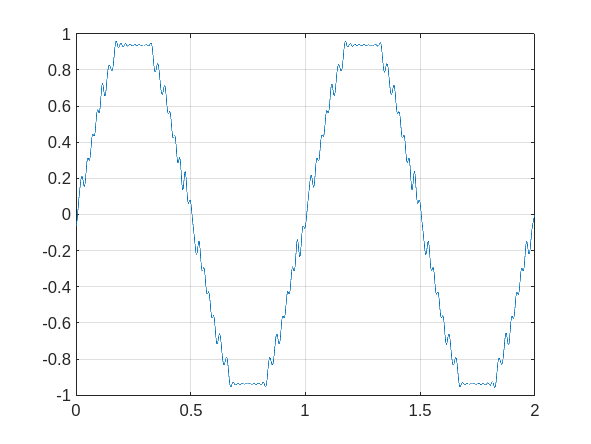


[y, t]= ReconstroiSinal(quants, Ta);
plot(t, y)
grid